close all; clear; clc

## 1. Dataset

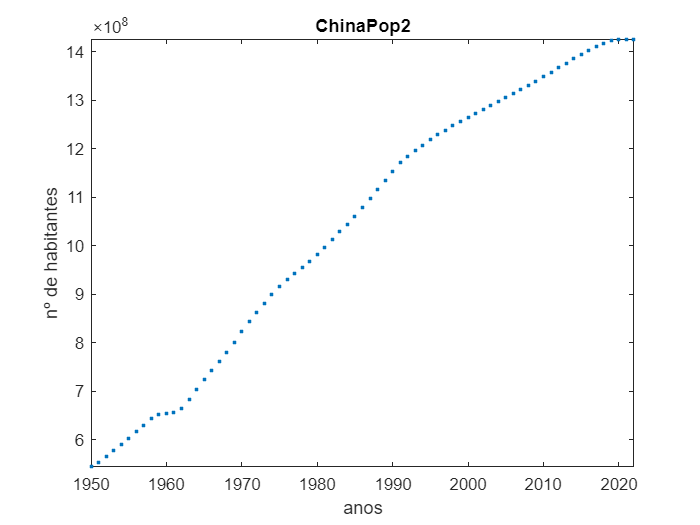

data = readmatrix ('ChinaPop2.csv');

x = data(:,1); % : significa que vamos buscar todas as linhas, 1 significa que e da primeira coluna. 
y = data(:,2); % irá buscar todas as linhas da segunda coluna.

m = length(x);

% Contruir gráfico
figure;
plot(x,y,'.'); 
xlabel('anos');
ylabel('nº de habitantes'); 
title('ChinaPop2');
axis ([min(x) max(x) min(y) max(y)]);

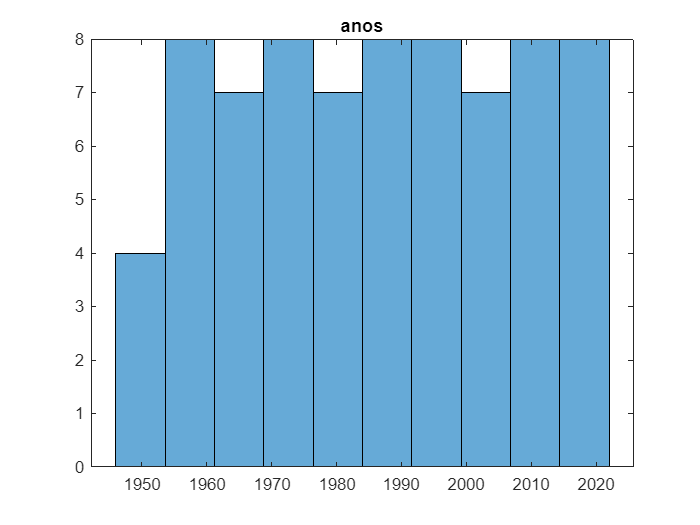


% Contruir o histograma
figure;
histogram(x,10);
title('anos');

## 2. Normalização do Dataset    

Normalização é utilizada para colocar os valores entre 0 e 1

Para que a mesmo tendo valores muito grandes e muito pequenos, ambos sejam relevantes.

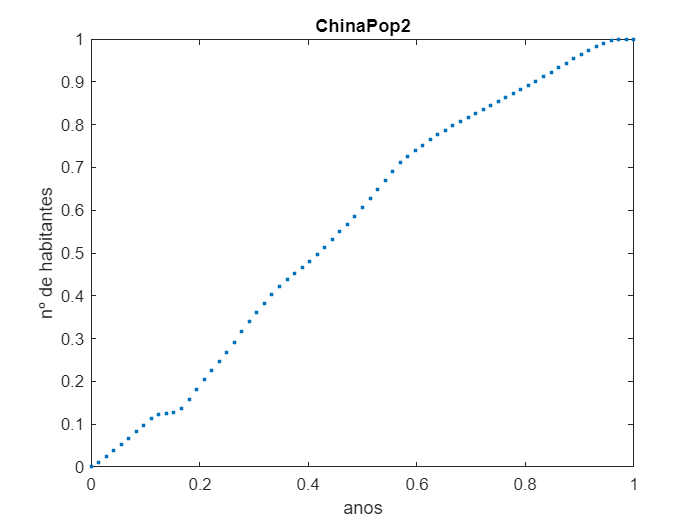

% Normalização Usando o min e max
xnorm = (x-min(x))/(max(x)-min(x));
ynorm = (y-min(y))/(max(y)-min(y));

figure;
plot(xnorm, ynorm, '.');
xlabel('anos');
ylabel('nº de habitantes'); 
title('ChinaPop2');

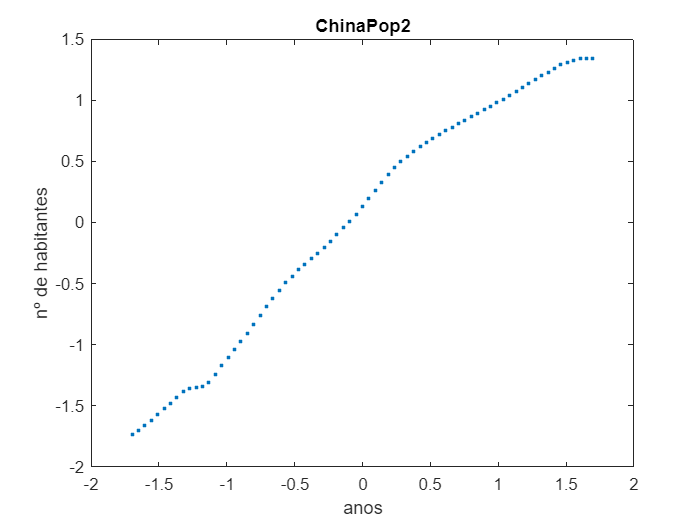


% Normalização usando desvio padrão e media
xnorm2 = (x-mean(x))/std(x);
ynorm2 = (y-mean(y))/std(y);

figure;
plot(xnorm2, ynorm2, '.');
xlabel('anos');
ylabel('nº de habitantes'); 
title('ChinaPop2');

## 3. Regressão Linear Simples

### 3.1. Obter a linha ax+b do modelo de regressão linear

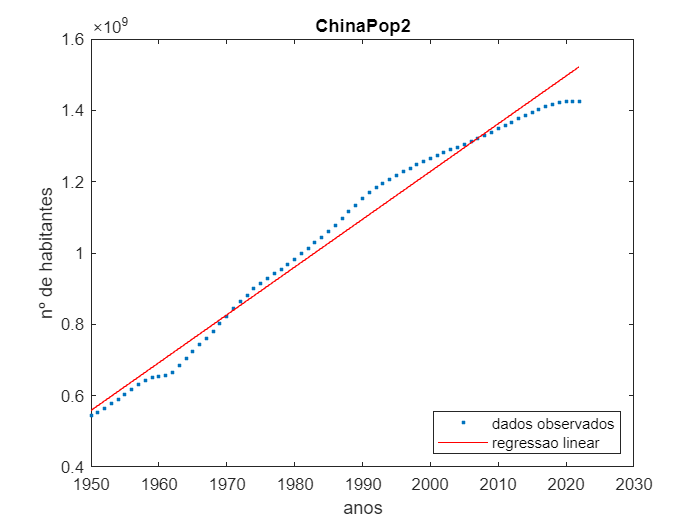

% Obter os parametros da reta da regressão linear
% p obtem o a e b da reta y=ax+b
p = polyfit(x, y, 1);

figure;
plot(x,y,'.');
hold on;
plot([min(x) max(x)],p(1)*[min(x) max(x)]+p(2),'r');
xlabel('anos');
ylabel('nº de habitantes'); 
title('ChinaPop2');
legend('dados observados', 'regressao linear', 'Location','southeast');

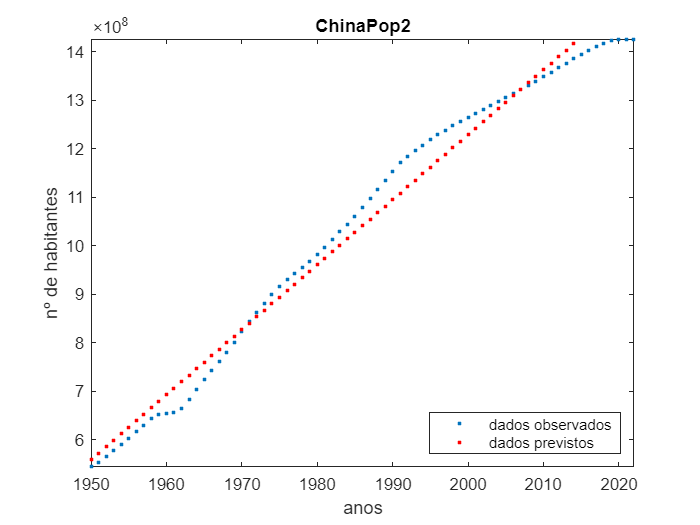


% Obter valores previstos para o numero habitantes usando a reta de
% regressao linear

y_pred = polyval (p, x);

figure;
plot(x,y,'.');
hold on;
plot(x,y_pred,'.r');
axis ([min(x) max(x) min(y) max(y)]);
xlabel('anos');
ylabel('nº de habitantes'); 
title('ChinaPop2');
legend('dados observados', 'dados previstos', 'Location','southeast');

### 3.2. Métricas

% Coeficiente de Pearson.
c = corr(x,y);
disp(['A correlação entre os anos e o nº habitantes é ' num2str(c)]);

A correlação entre os anos e o nº habitantes é 0.99106



SSE = sum((y-y_pred).^2);
disp(['Sum of Squared Errors : SSE = ' num2str(SSE)]);

Sum of Squared Errors : SSE = 1.054891533544473e+17


MSE = sum((y-y_pred).^2)/m;
disp(['Mean Squared Error : MSE = ' num2str(MSE)]);

Mean Squared Error : MSE = 1445056895266402


MAE = sum(abs(y-y_pred))/m;
disp(['Mean Absolute Error : MAE = ' num2str(MAE)]);

Mean Absolute Error : MAE = 32633646.7331


RMSE = sqrt(sum((y-y_pred).^2)/m);
disp(['Root Mean Squared Error : RMSE = ' num2str(RMSE)]);

Root Mean Squared Error : RMSE = 38013903.973


### 3.3. Dividir o dataset para treino e teste

Usamos o treino usando alguns dados para ensinar e depois damos dados diferentes no de teste para ver se aprendeu alguma coisa ou apenas decorou os dados de treino.

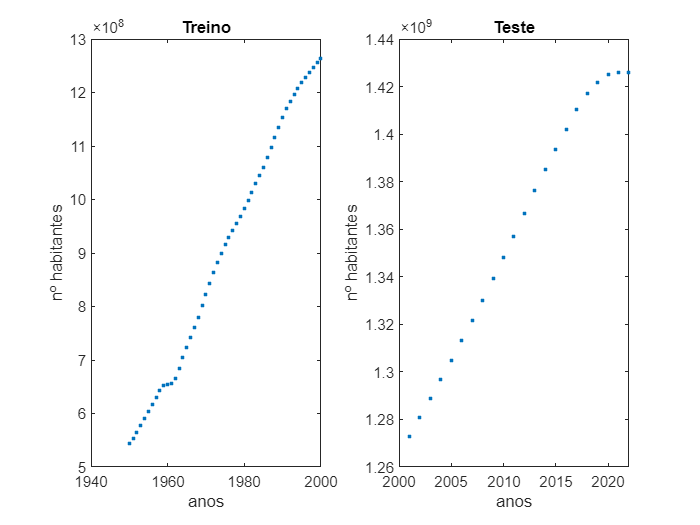

% Percentagem de dados usados para treino.
T = 0.7;

% Percentabem de dados usados para teste.
TestProp = 1-T;

% Escolher aleatoriamente os T * m exemplos que serao usados no dataset
%------------------------------------------------------------
% Sao utilizados os dados mais antigos
nrExemplosTreino = round(T * m);
indicesParaTreino = 1:nrExemplosTreino;
indicesParaTeste = nrExemplosTreino +1 : m;
% Em baixo sao utilizados os dados aleatoriamente
% permutacoes = randperm(m);
% indicesParaTreino = sort(permutacoes(1:nrExemplosTreino));
% indicesParaTeste = setdiff(1:m,indicesparatreino);
% ------------------------------------------------------------

% Dividir o dataset em duas partes
% o treino: x_train, y_train
x_train = x(indicesParaTreino);
y_train = y(indicesParaTreino);

% o teste: x_test, y_test
x_test = x(indicesParaTeste);
y_test = y(indicesParaTeste);

% funcao plot para visualizar os meus dados 
figure;
subplot(1,2,1);
plot(x_train,y_train,'.');
xlabel('anos');
ylabel('nº habitantes');
title('Treino');

subplot(1,2,2);
plot(x_test,y_test,'.');
xlabel('anos');
ylabel('nº habitantes');
title('Teste');

### 3.4. Treinar e Testar o modelo

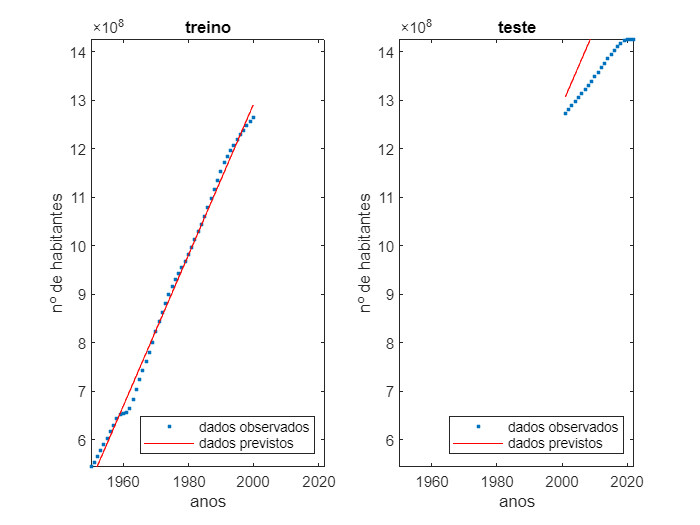

% Usamos o polyfit para retreinar o modelo
p = polyfit(x_train, y_train, 1);

% Usando a funcao polyval criar outputs para os modelos
y_pred_train = polyval(p, x_train);
y_pred_test = polyval(p, x_test);

% Funcao plot para visulizar os dados
figure;
subplot(1,2,1);
plot(x_train,y_train,'.');
hold on;
plot(x_train,y_pred_train,'r');
axis([min(x) max(x) min(y) max(y)]);
xlabel('anos');
ylabel('nº de habitantes');
title('treino')
legend('dados observados', 'dados previstos', 'Location','southeast');

subplot(1,2,2);
plot(x_test,y_test,'.');
hold on;
plot(x_test,y_pred_test,'r');
axis([min(x) max(x) min(y) max(y)])
xlabel('anos');
ylabel('nº de habitantes');
title('teste')
legend('dados observados', 'dados previstos', 'Location','southeast')


SSE = sum((y_test-y_pred_test).^2);
disp(['Sum of Squared Errors : SSE = ' num2str(SSE)]);

Sum of Squared Errors : SSE = 3.215262616591457e+17


MSE = sum((y_test-y_pred_test).^2)/m;
disp(['Mean Squared Error : MSE = ' num2str(MSE)]);

Mean Squared Error : MSE = 4404469337796516


MAE = sum(abs(y_test-y_pred_test))/m;
disp(['Mean Absolute Error : MAE = ' num2str(MAE)]);

Mean Absolute Error : MAE = 33435868.9483


RMSE = sqrt(sum((y_test-y_pred_test).^2)/m);
disp(['Root Mean Squared Error : RMSE = ' num2str(RMSE)]);

Root Mean Squared Error : RMSE = 66366176.1577


## 4. Regressão não Linear (Polinomial)

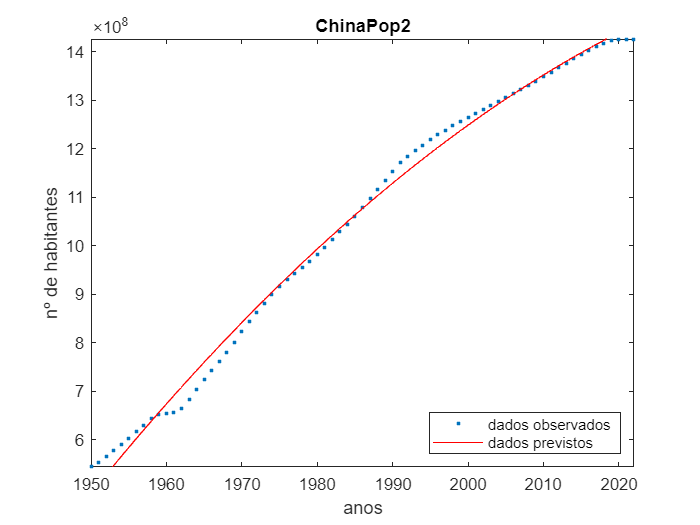

warning off

p = polyfit(x, y, 2);

y_pred = polyval(p, x);

figure;
plot(x,y,'.');
hold on;
plot(x,y_pred,'r');
axis([min(x) max(x) min(y) max(y)]);
xlabel('anos');
ylabel('nº de habitantes');
title('ChinaPop2');
legend('dados observados', 'dados previstos', 'Location','southeast');


SSE = sum((y-y_pred).^2);
disp(['Sum of Squared Errors : SSE = ' num2str(SSE)]);

Sum of Squared Errors : SSE = 3.132248987330623e+16


MSE = sum((y-y_pred).^2)/m;
disp(['Mean Squared Error : MSE = ' num2str(MSE)]);

Mean Squared Error : MSE = 429075203743921


MAE = sum(abs(y-y_pred))/m;
disp(['Mean Absolute Error : MAE = ' num2str(MAE)]);

Mean Absolute Error : MAE = 16214302.0885


RMSE = sqrt(sum((y-y_pred).^2)/m);
disp(['Root Mean Squared Error : RMSE = ' num2str(RMSE)]);

Root Mean Squared Error : RMSE = 20714130.5331


## 5. Gradiente Descendente

a = rand();
b = rand();

LR = 0.01;

y_pred = a * xnorm + b;
SSE = sum((ynorm-y_pred).^2);
disp(['Sum of Squad Errors : SSE = ' num2str(SSE)]);

Sum of Squad Errors : SSE = 41.6545


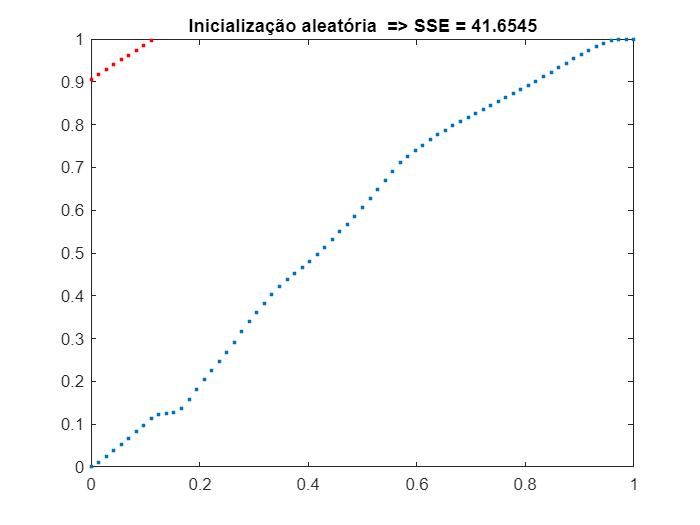

figure;
plot(xnorm,ynorm,'.');
hold on;
plot(xnorm,y_pred,'.r');
axis([min(xnorm) max(xnorm) min(ynorm) max(ynorm)]);
title(['Inicialização aleatória  => SSE = ' num2str(SSE)]);


for it = 1 : 100
    a = a - LR * 2 * sum((y_pred-ynorm).*xnorm);
    b = b - LR * 2 * sum(y_pred-ynorm);
    y_pred = a * xnorm + b;
end

disp('Coeficientes pelo Gradiente Descendente');

Coeficientes pelo Gradiente Descendente


disp(['a = ' num2str(a)])

a = 1.0938


disp(['b = ' num2str(b)])

b = 0.01654



SSE = sum((ynorm-y_pred).^2);
disp(['Sum Of Squared Errors : SSE = ' num2str(SSE)]);

Sum Of Squared Errors : SSE = 0.13563


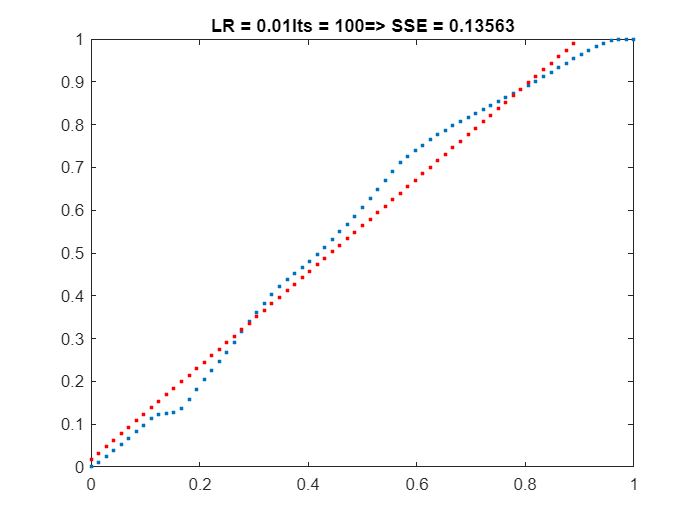

figure;
plot(xnorm,ynorm,'.');
hold on;
plot(xnorm,y_pred,'.r');
axis([min(xnorm) max(xnorm) min(ynorm) max(ynorm)]);
title(['LR = ' num2str(LR) 'Its = ' num2str(it) '=> SSE = ' num2str(SSE)]);